# EL6023 Final Project

Amritpal Singh

Kubilay Ulger

In this project we simulate a MIMO channel using data from Minsheng's data set. 

## Loading Data and Getting Path Information

Loading Data

load roomPathData.mat

Creating antenna element, boresight in positive x-axis. 

fc = pathData.fc; %Carrier Frequency
elem = design(patchMicrostrip, fc); %Simple antenna element
elem.Tilt = 90; 
elem.TiltAxis = [0 1 0];


Antenna platforms

%We took these antenna numbers from a demo, they are the usual arrays in
%mmWave
nantgNB = [4,4]; % 16 Antennas at transmitter
nantUE = 8; % 8 Antennas at receiver

lambda = physconst('LightSpeed')/fc; %Wavelength
dstep = lambda/2; %Distance between antennas

arrgNB = phased.URA(nantgNB,dstep,"ArrayNormal","x"); %URA for transmitter
arrUE = phased.ULA(nantUE,dstep,"ArrayAxis","x"); %ULA for receiver

arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

Looking at Tx and Rx antennas

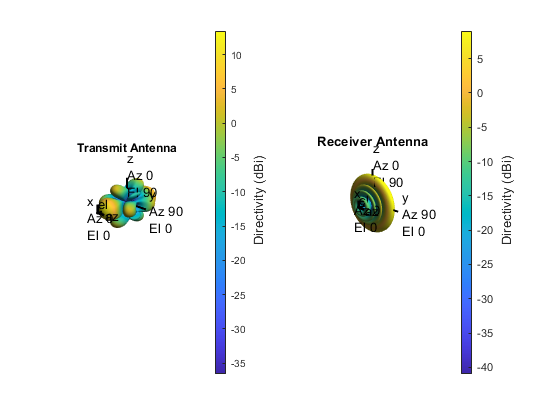

figure(1)
subplot(1,2,1)
arrgNB.pattern(fc);
title('Transmit Antenna')
subplot(1,2,2);
arrUE.pattern(fc);
title('Receiver Antenna')

Paths, gains, delay, angles

TODO: Get 

rxNum = 15; %Receiver antenna picked

txPos = pathData.txPos;
rxPos = pathData.rxPos(rxNum,:);

txPow = 15; %dB
nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Thermal noise

%Path Stuff
npaths = pathData.npaths(rxNum,:);
pl = pathData.pl(rxNum,:);
gain = txPow - pl'  - nf - Ekt - 10*log10(bw);
dly = pathData.dly(rxNum,:);

aoaAz = pathData.aoaAz(rxNum,:)';
aoaEl = pathData.aoaEl(rxNum,:)';
aodAz = pathData.aodAz(rxNum,:)';
aodEl = pathData.aodEl(rxNum,:)';

- Try LOS, NLOS, …

- Create a FD channel 

- Use the one from the previous lab

- Enter the parameters from that data

- Simulate an OFDM over a slot

## **OFDM CHANNEL**

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -100;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

Calculating average of H'*H

Q = pagemtimes(permute(conj(chanGrid),[2 1 3 4]),chanGrid);
Q = squeeze(mean(mean(Q,3),4));

## Transmitter

Precoder

nstream = 2;
[V,D] = eig(Q);
Fprecoder = V(:,end-nstream+1:end);
G = pagemtimes(chanGrid,Fprecoder); %Pre-coded channel

Now for the transmitter we create a pdfschConfig as usual, but we now have NumLayers = nstream. So we create a tx object.

mcsInd = 12;

Modulation = '16QAM';
targetCodeRate = 434/1024;

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', nstream);
  %  'EnablePTRS', 1,...
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate, 'nant',16);

Now we create a txGrid

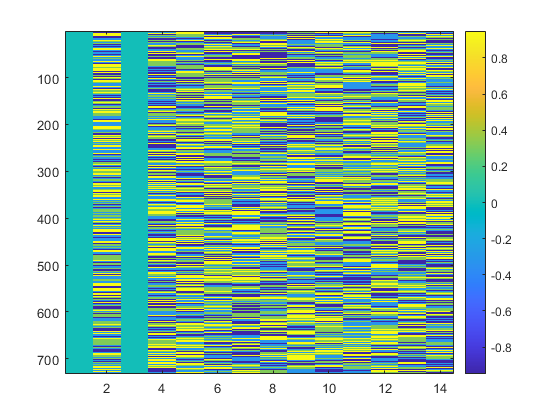

txGrid = tx.step(); 
figure(2)
imagesc(real(txGrid(:,:,1)))
colorbar

We precode the txGrid by the precoder calculated above

txGrid = permute(txGrid,[3,1,2]); %Getting right dimension order
txGrid = reshape(txGrid,[nstream,1,732,14]); %Adding an empty 1x dimension for matrix multiplication
txGridPrecoded = pagemtimes(Fprecoder,txGrid); %Perfoming matrix multiplication to first 2 dimensions. Hence we precode each RE

Now we pass precoded grid through the chanGrid

rxgrid = pagemtimes(chanGrid,txGridPrecoded); 

## Receiver

Now we have to perform LMMSE before decoding

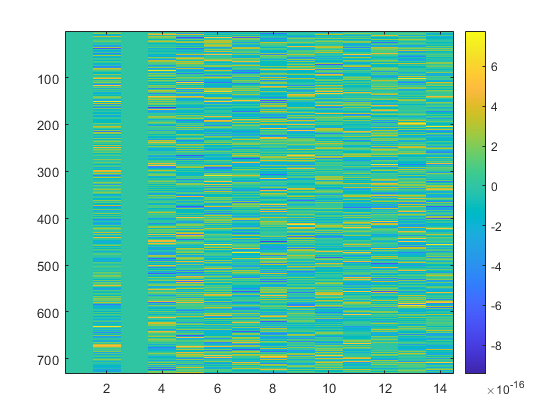

Gconj = permute(conj(G),[2,1,3,4]); %Hermitian of the precoded channel (known at the receiver)
Flmmse = zeros(size(Gconj)); 
for i=1:732
    for j = 1:14
        Flmmse(:,:,i,j)=(Gconj(:,:,i,j)*G(:,:,i,j))^-1*Gconj(:,:,i,j); %LMMSE decoder at each resource element
    end
end

Heq = pagemtimes(Flmmse,G); %Equalized channel, it should be close to identity matrix at high SNR

rxGridEq = squeeze(pagemtimes(Flmmse,rxgrid)); %Equalizing received signal

%Test: Since we don't have noise rxGridEq and txGrid should be same
figure(3)
imagesc(real(squeeze(rxGridEq(1,:,:)))-squeeze(real(txGrid(1,1,:,:))))
colorbar

order of 10^-16 for the difference so we did LMMSE correctly.

## Demodulation

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGridEq, Heq, 0); %Demodulation

%Test
txBits = tx.txBits{1};
rxBits = rx.rxBits;



CorrectBits = length(find(rxBits == txBits));
TotalBits = length(txBits);



fprintf('%d,%d',CorrectBits,TotalBits)

14901,29704